

r=0.26; L=35/100; M=51/1000; g=9.81;

load("0.02_1.mat");
data_pulses=iddata(Pen_0.signals.values(2:end),theta_0.signals.values(2:end),theta_0.time(2));
init_sys=idtf([-3/2*r/L 0 0],[1 NaN 3/2*g/L]);
init_sys.Structure.num.Free=[false false false];
init_sys.Structure.den.Free=[false true false];
init_sys.Structure.IODelay.Free=false;
sys_pulses=tfest(data_pulses,init_sys);

c=2.858*M*L^2/3;

clear;
r=0.26; L=35/100; M=51/1000; g=9.81;
km=24.2e-3;
kb=km;
Ra=2.21;
Nr=4.5;
ku=12;
kp=2550;
tau_p=0.36;
f=33.879682/kp-0.005366;
J=tau_p*(f+0.005366);
c=2.858*M*L^2/3;

s=tf('s');
q=2*M*L^2*s^2+6*c*s+3*M*L*g;
Py=180/pi*(ku*km*Nr/Ra)*q/(s*((J+M*r^2)*s+f)*q-1.5*(M*L*r)^2*s^4+s*kb*km*Nr^2/Ra*q);
Pt=-3*M*L*r*s^2/q;

a1=load("0.02_2.mat");
a2=load("C2_step.mat");
a3=load("C2_2Hz.mat");
a4=load("C2_3Hz.mat");

C2= (0.4048*s^2 + 2.823*s + 2.757)/(10*s^2 + 237.6*s);

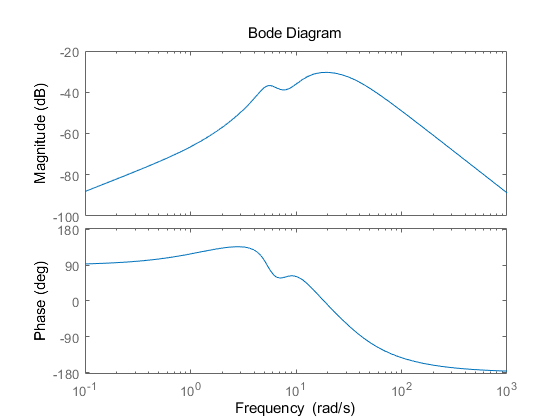

F=30^2/(s^2+1.6*30*s+30^2);
P=F*C2/(1+C2*Py);
bode(P)